subj = 13;


erf_osc_datainfo;

subjects =   1×18 struct array with fields:

    channels
    dataset
    logfile
    headshape
    mri
    mridir
    ecgcomp
    eyecomp
    badtrials
    aseo
    gammaband
    gammapeak


subjects =   1×26 struct array with fields:

    channels
    dataset
    logfile
    headshape
    mri
    mridir
    ecgcomp
    eyecomp
    badtrials
    aseo
    gammaband
    gammapeak


subject = subjects(subj);


[p,f,e]       = fileparts(subject.dataset);
basedir       = strrep(p, 'raw', 'processed');
filename_data = fullfile(basedir, 'cleandata.mat');
load(filename_data);

[data_onset, data_shift] = erfosc_getdata(dataClean, []);

the call to "ft_selectdata" took 3 seconds and required the additional allocation of an estimated 0 MB
the input is raw data with 270 channels and 301 trials


the call to "ft_redefinetrial" took 1 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 2 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 4 seconds and required the additional allocation of an estimated 1031 MB
the input is raw data with 270 channels and 301 trials


the call to "ft_redefinetrial" took 1 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 3 seconds and required the additional allocation of an estimated 353 MB
the input is raw data with 270 channels and 301 trials


the call to "ft_redefinetrial" took 1 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 3 seconds and required the additional allocation of an estimated 1112 MB
the input is raw data with 270 channels and 301 trials
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB
resampling data
resampling data in trial 2 from 301
resampling data in trial 4 from 301
resampling data in trial 6 from 301
resampling data in trial 8 from 301
resampling data in trial 10 from 301
resampling data in trial 13 from 301
resampling data in trial 15 from 301
resampling data in trial 17 from 301
resampling data in trial 19 from 301
resampling data in trial 21 from 301
resampling data in trial 23 from 301
resampling data in trial 26 from 301
resampling data in trial 29 from 301
resampling data in trial 31 from 301
resampling data in trial 33 from 301
resampling data in trial 36 from 301
resampling data in trial 39 from 301
resampling data in trial 41 from 301
resampling data in trial 45 from 301
resampling data in tr

clear dataClean;

% identify channel-of-interest
cfg = [];
cfg.preproc.demean='yes';
cfg.preproc.baselinewindow = [-.1 0];
cfg.vartrllength = 2;
tlck = ft_timelockanalysis(cfg, data_shift);

the input is raw data with 270 channels and 301 trials


> In fixsampleinfo (line 94)
  In ft_datatype_raw (line 147)
  In ft_checkdata (<a href="matlab: opentoline('/home/language/jansch/matlab/fieldtrip/utilities/ft_checkdata.m',264,0)">line 264</

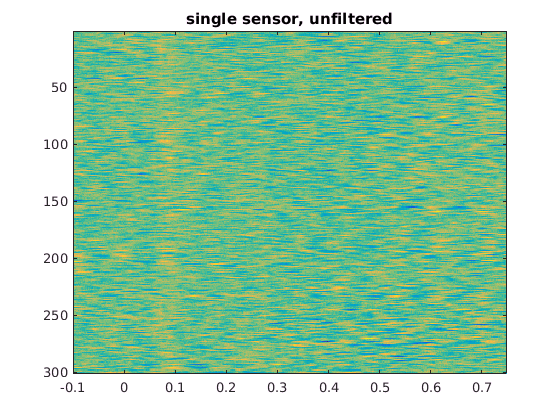


% use ft_topoplotER, I selected MRP52, based on the 0.07-0.08 time window,
% indx 221

% identify parcel-of-interest
loaddir = '/home/language/jansch/erfosc';
load(fullfile(loaddir, sprintf('sub-%03d_lcmv', subj)), 'source_parc', 'noise');
% I selected R_18_B05_04, indx 360

dat1 = cellrowselect(data_shift.trial, 221);
dat2 = source_parc.F{360}(1,:)*data_shift.trial;

dat1 = cat(1,dat1{:}); dat1 = dat1(:,391:end);
dat2 = cat(1,dat2{:}); dat2 = dat2(:,391:end);

tim = tlck.time(391:end);

figure;imagesc(tim,1:size(dat1,1),dat1, [-10e-13 10e-13]); title('single sensor, unfiltered'); colormap(flipud(brewermap(64, 'RdBu')));

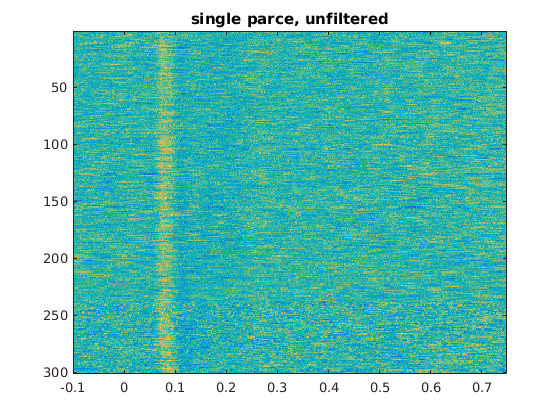

figure;imagesc(tim,1:size(dat2,1),dat2, [-4e-12 4e-12]); title('single parcel, unfiltered');colormap(flipud(brewermap(64, 'RdBu')));

Lowpass filtering data: onepass-zerophase, order 198, hamming-windowed sinc FIR
  cutoff (-6 dB) 40 Hz
  transition width 10.0 Hz, passband 0-35.0 Hz, stopband 45.0-300 Hz
  max. passband deviation 0.0022 (0.22%), stopband attenuation -53 dB


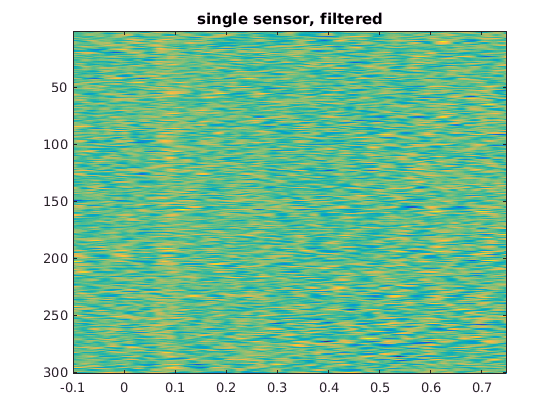

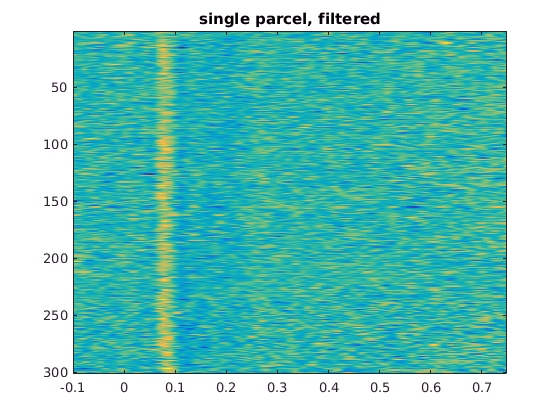

%figure;plot(tim,dat1,'b');hold on;plot(tim,mean(dat1,1),'r','linewidth',2)
%figure;plot(tim,dat2,'b');hold on;plot(tim,mean(dat2,1),'r','linewidth',2)

figure;imagesc(tim,1:size(dat1,1),ft_preproc_lowpassfilter(dat1,600,40,[],'firws'), [-1e-12 1e-12]); title('single sensor, filtered'); colormap(flipud(brewermap(64, 'RdBu')));
figure;imagesc(tim,1:size(dat2,1),ft_preproc_lowpassfilter(dat2,600,40,[],'firws'),[-4e-12 4e-12]); title('single parcel, filtered'); colormap(flipud(brewermap(64, 'RdBu')));